close; clear; clc;

%% Parametry
fs = 16000; % Vzorkovací frekvence (16 kHz)
segment_duration = 2; % Délka segmentu (2 s)
segment_samples = fs * segment_duration; % Počet vzorků v segmentu
p = '2502'; % přidělené číslo
num_records = 5; % Počet nahrávek
e_treshold = -4; % Práh pro detekci energie

% Kontrola existence adresáře
output_dir = sprintf('p%s', p);
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

%% Zpracování jednotlivých nahrávek
for n = 1:num_records
    % Načtení nahrávky
    file_name = sprintf('nahrávka_%02d.wav', n);
    if exist(file_name, 'file')
        [audio, fs] = audioread(file_name);
    else
        warning("Soubor %s nebyl nalezen!", file_name);
        break;
    end

    % Přidání náhodného šumu
    noise_level = 0.01 * std(audio); % adaptivní šum podle směrodatné odchylky
    y = audio + (2 * rand(length(audio), 1) - 1) * noise_level;

    % Filtrování horní propustí
    y = filter([1 -0.97], 1, y);

## **Segmentace na framy (25 ms s 10 ms krokem)**

    frame_length = round(fs * 0.025); % 25 ms
    frame_step = round(fs * 0.01); % 10 ms
    num_frames = floor((length(y) - frame_length) / frame_step) + 1;
    frames = zeros(frame_length, num_frames);

    for j = 1:num_frames
        start_idx = (j - 1) * frame_step + 1;
        end_idx = start_idx + frame_length - 1;
        frames(:, j) = y(start_idx:end_idx);
    end

## Výpočet energie pro každý frame s přidáním eps proti výpočtu log(0)

    energy = log(sum(frames .^ 2)+eps);

## **Detekce všech řečových úseků s tolerancí krátkých pauz do 0.4s**

    speech_segments = [];
    in_speech = false;
    pause_tolerance = round(0.4 / 0.01);
    pause_counter = 0;

    for j = 1:num_frames
        current_time = (j - 1) * frame_step / fs; % čas ve vteřinách

        if energy(j) >= e_treshold
            if ~in_speech
                start_time = current_time; % začátek segmentu (v sekundách)
                in_speech = true;
            end
            pause_counter = 0;
        else
            if in_speech
                pause_counter = pause_counter + 1;
                if pause_counter > pause_tolerance
                    end_time = current_time - (pause_tolerance * frame_step / fs); % konec segmentu
                    speech_segments = [speech_segments; start_time, end_time];
                    in_speech = false;
                end
            end
        end
    end

    % Pokud řečový úsek končí na konci nahrávky
    if in_speech
        end_time = length(audio) / fs; % celková délka audia v sekundách
        speech_segments = [speech_segments; start_time, end_time];
    end


## Ukládání 2 s segmentů

    segment_counter = 0;
    segment_times = [];

    for k = 1:size(speech_segments, 1)
        word_start = speech_segments(k, 1);
        word_end = speech_segments(k, 2);
        word_center = (word_start + word_end) / 2;

        % Výpočet segmentu
        segment_start = max(0, word_center - segment_duration / 2);
        segment_end = min(length(audio) / fs, segment_start + segment_duration);
        start_sample = round(segment_start * fs) + 1;
        end_sample = min(round(segment_end * fs), length(audio));
        segment = audio(start_sample:end_sample);

        % Uložení segmentu
        segment_name = sprintf('%s/c%d_p%s_s%02d.wav', output_dir, segment_counter, p, n);
        segment_counter = segment_counter + 1;
        audiowrite(segment_name, segment, fs);

        % Uložení času segmentu pro graf
        segment_times = [segment_times; segment_start, segment_end];
    end

##     Vykreslení grafu

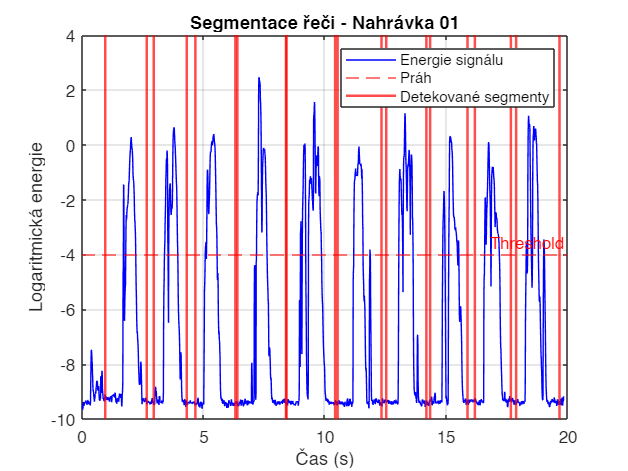

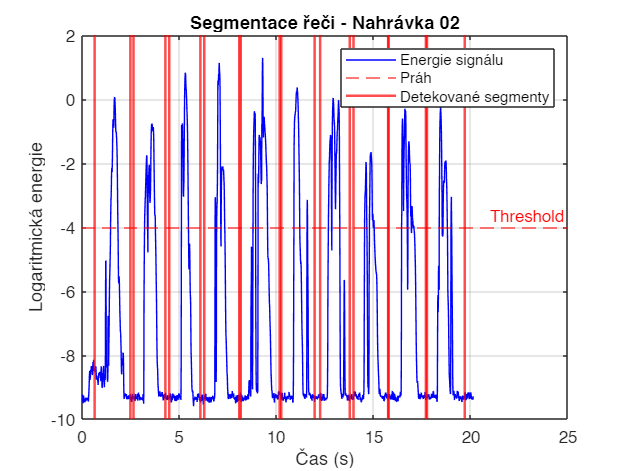

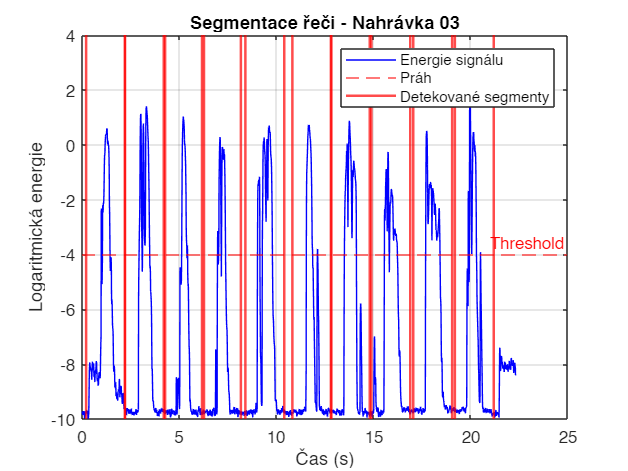

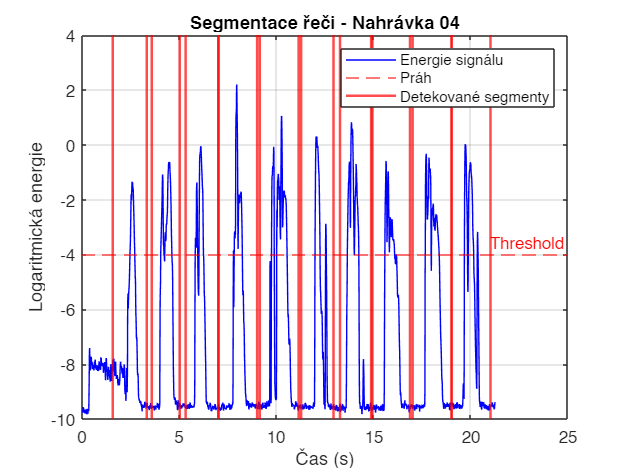

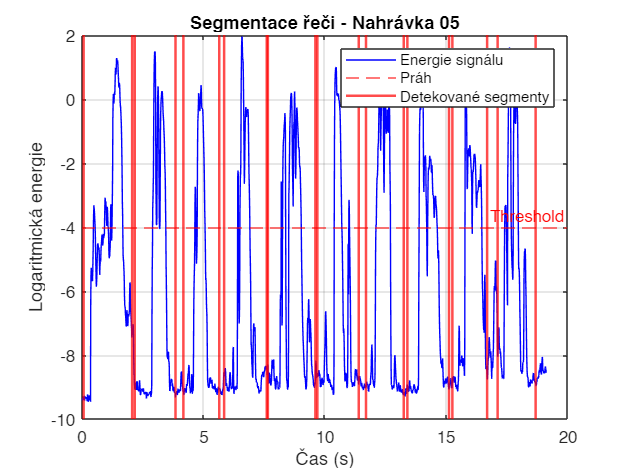

    figure;
    time_axis = (1:num_frames) * frame_step / fs; % Osa X v sekundách
    plot(time_axis, energy, 'b'); % Graf energie
    hold on;
    yline(e_treshold, 'r--', 'Threshold'); % Práh energie

    % Vyznačení segmentů řeči
    for k = 1:size(segment_times, 1)
        xline(segment_times(k, 1), 'r', 'LineWidth', 1.5); % Začátek segmentu
        xline(segment_times(k, 2), 'r', 'LineWidth', 1.5); % Konec segmentu
    end

    title(sprintf('Segmentace řeči - Nahrávka %02d', n));
    xlabel('Čas (s)');
    ylabel('Logaritmická energie');
    legend('Energie signálu', 'Práh', 'Detekované segmenty');
    grid on;

end


disp("Hotovo! Všechny segmenty byly vytvořeny.");

Hotovo! Všechny segmenty byly vytvořeny.
